## TESA Topgun Rally pre-camp

[MATLAB Online](https://matlab.mathworks.com/) = Use MATLAB and Simulink through your web browser

- Get 1 vCPU with 4GB of memory (provided compute) with ability to burst depending on load 

- Get 5GB (free) or 20GB (licensed) storage through MATLAB Drive

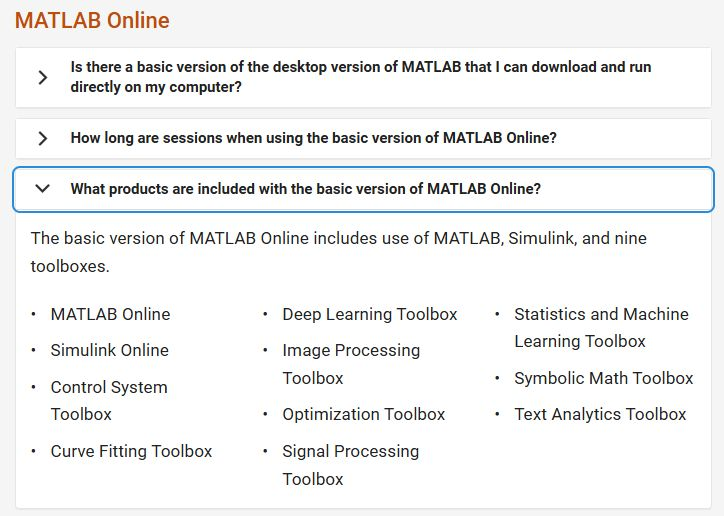

- Check compiler setting

mex -setup

MEX configured to use 'gcc' for C language compilation.

To choose a different language, select one from the following:
 mex -setup C++ 
 mex -setup FORTRAN


mex -setup C++

MEX configured to use 'g++' for C++ language compilation.


### C generation

#### Step 1 prepare function

- Define a function

- Test the function

dummy_data = int32(randi([-8388608, 8388607], 1, 160));
out = testFcn(dummy_data)

out = 0.5580

coder.screener('testFcn')

#### Step 2 generate code

cfg = coder.config('lib');
cfg.TargetLang = 'C';
cfg.InlineBetweenUserFunctions = 'Readability';
codegen -config cfg testFcn -args {dummy_data} -report

Code generation successful: View report



#### Step 3 pack generated code

cd codegen/lib/testFcn/
load buildInfo.mat
packNGo(buildInfo,'packType', 'hierarchical', 'fileName', 'testFcn');

#### Step 4 apply code

- Copy code into /src and /include of ESP32 Platform.io project

- Modify main.cpp

- Build and run

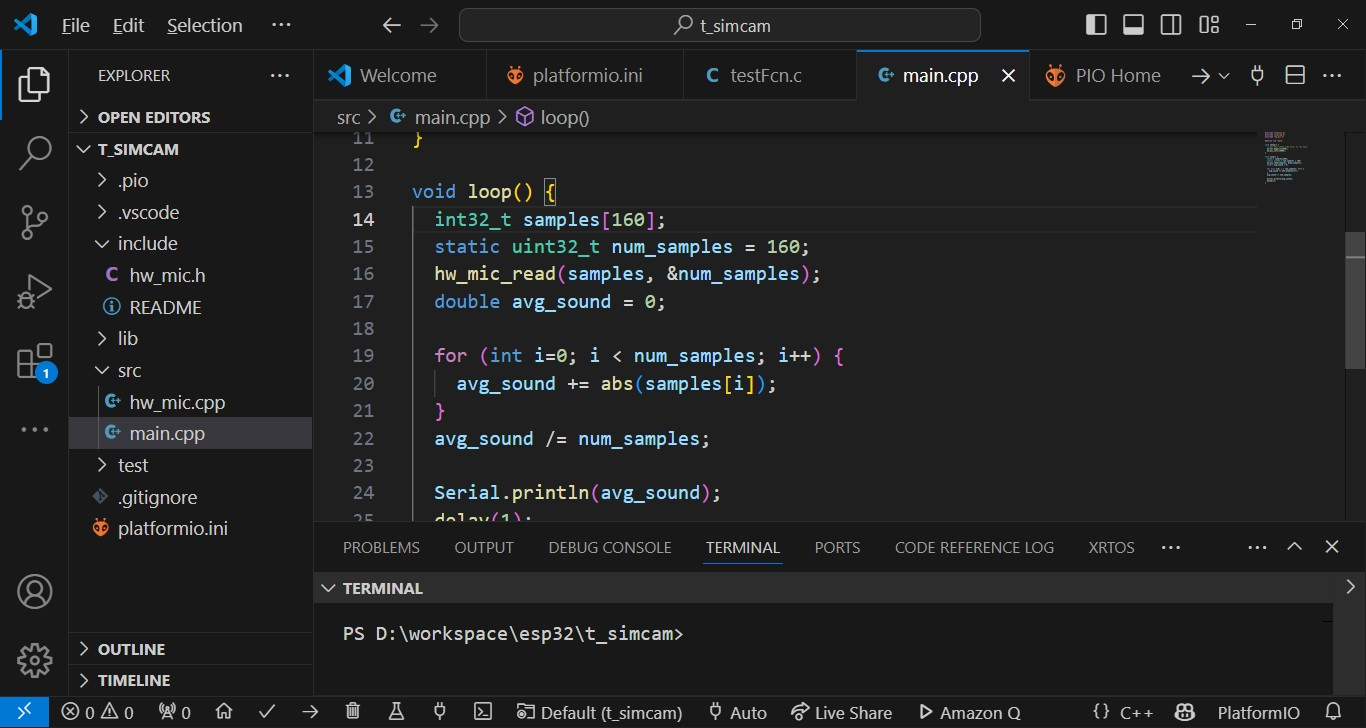

### C++ generation

#### Step 1 prepare class and function

- Define a class.

- Define a function to call object's method.

- Test the function

out = testMyClass(1, [10, 20,-30, 40])

out = 100

out = testMyClass(2, [10, 20,-30, 40])

out = 54.7723

out = testMyClass(3, [10, 20,-30, 40])

out = 40

coder.screener('testMyClass')

#### Step 2 generate code

cfg = coder.config('lib');
cfg.TargetLang = 'C++';
cfg.InlineBetweenUserFunctions = 'Readability';
codegen -config cfg testMyClass -args {1, [10,20,30,40]} -report

Code generation successful: View report



#### Step 3 pack generated code

cd codegen/lib/testMyClass/
load buildInfo.mat
packNGo(buildInfo,'packType', 'hierarchical', 'fileName', 'testMyClass');

- Download from MATLAB Drive to PC.

#### Step 4 move gen code to WSL

- Install [Windows SubSystem for Linux](https://learn.microsoft.com/en-us/windows/wsl/install), and [Visual Studio Code](https://code.visualstudio.com/Download), 

- Activate **Remote Explorer** in VS Code Extensions.

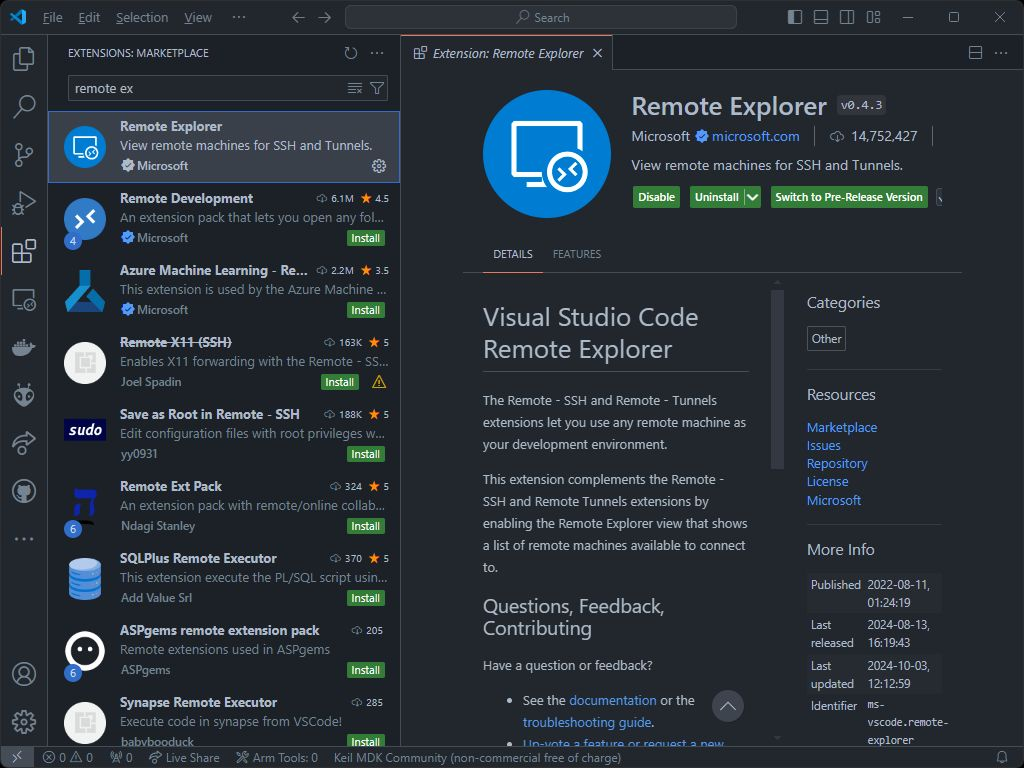

- Start VS Code, choose **Remote Explorer** extension, connect to **WSL Targets**, and start **New Terminal**.

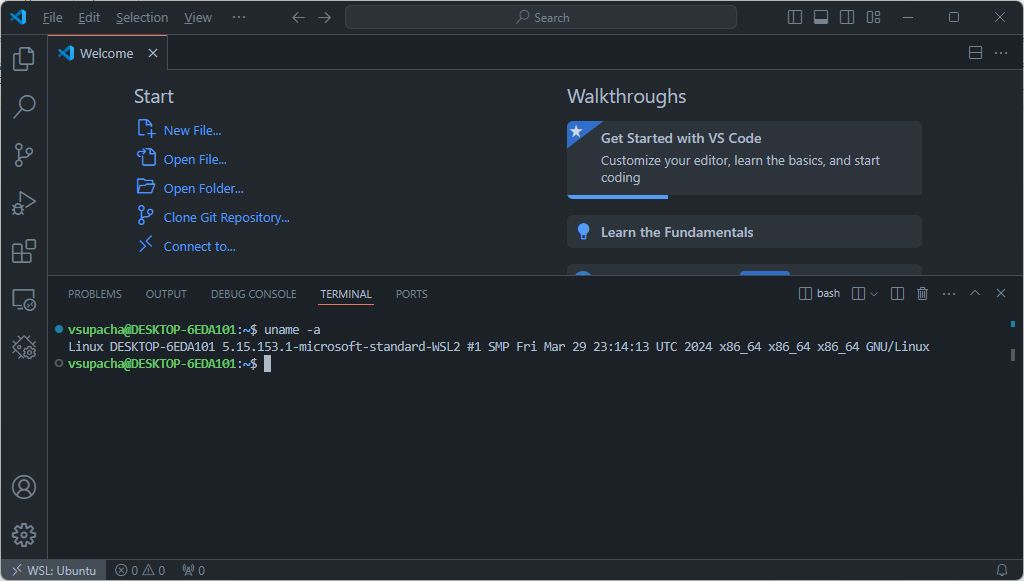

- Use apt command to install required software: `sudo apt install gcc unzip`

- Copy file from Windows into WSL environment: `cp /mnt/c/Users/DELL/Downloads/testMyClass.zip ./`

- Unzip file: `unzip testMyClass.zip`

- Unzip file: `unzip sDirFiles.zip`

- Unzip file: `unzip mlrFiles.zip `

#### Step 5 build and run code

- Move into gen code folder: `cd codegen/lib/testMyClass`

- Prepare code main.cpp

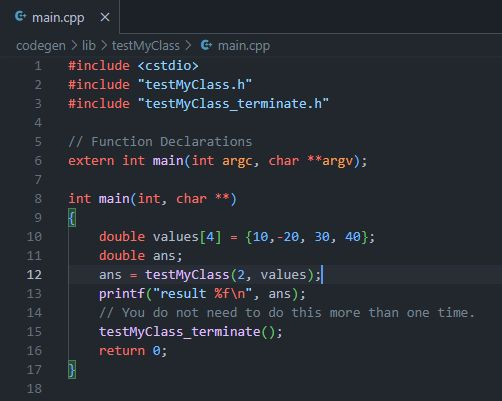

- Build application: `g++ -I ../../../MATLAB/extern/include/ testMyClass.cpp MyClass.cpp testMyClass_initialize.cpp testMyClass_terminate.cpp norm.cpp main.cpp -o app`

- Run application: `./app`